**第8章 数值积分**

### **8.1**** 插值型求积方法**

        一元函数定积分的数学表示为

                            
$$I=\int_a^b f\left(x\right)\textrm{dx}$$
               
$$\left(8-1\right)$$
      

        又有Newton-Leibniz公式

                                                                                        
$$\int_a^b f\left(x\right)\textrm{dx}=F\left(b\right)-F\left(a\right)$$
        
$$\left(8-2\right)$$


        用插值多项式$L_n \left(x\right)$替换$\left(8-1\right)$中的被积函数$f\left(x\right)$，然后计算$I=\int_a^b L_n \left(x\right)\textrm{dx}$作为积分的近似值，这样建立的求积公式称为插值型求积公式。

        设给定一组节点$a=x_0 <x_1 <\ldotp \ldotp \ldotp <x_n =b$，且$f\left(x\right)$在这些节点上的值为$f\left(x_k \right)$，则可作$n$次插值多项式$L_n \left(x\right)=\sum_{k=0}^n f\left(x_k \right)l_k \left(x\right)$，其中$l_k \left(x\right)=\prod_{j=0,j\not= k}^n \frac{x-x_j }{x_k -x_j }$是插值基数。

        用$L_n \left(x\right)$替换$\left(8-1\right)$中的$f\left(x\right)$，有

                                    
$$I_n \left(f\right)=\int_a^b L_n \left(x\right)\textrm{dx}=\int_a^b \sum_{k=0}^n f\left(x_k \right)l_k \left(x\right)\textrm{dx}\sum_{k=0}^n \left\lbrack \int_a^b l_k \left(x\right)\textrm{dx}\right\rbrack f\left(x_k \right)=\sum_{k=0}^n A_k f\left(x_k \right)$$
               
$$\left(8-3\right)$$


其中$A_k =\int_a^b l_k \left(x\right)\textrm{dx}$。

        下面讨论$A_k$的计算，把积分区间$\left\lbrack a,b\right\rbrack$分为$n$等份，令步长$h=\frac{b-a}{n}$，则$x_k =x_0 +\textrm{kh}\left(k=0,1,2,\ldotp \ldotp \ldotp ,n\right)$，作变换$t=\frac{x-x_0 }{h}$，代入$A_k$中得

                                    
$$A_k =\int_a^b l_k \left(x\right)\textrm{dx}=h\int_0^n \prod_{j=0,j\not= k}^n \frac{t-j}{k-j}\textrm{dt}=\frac{{\left(-1\right)}^{n-k} h}{\left(n-k\right)!k!}\int_0^n \prod_{j=0,j\not= k}^n \left(t-j\right)\textrm{dt}\;\;\left(k=0,1,2,\ldotp \ldotp \ldotp ,n\right)$$
         
$$\left(8-4\right)$$


这种等距节点的插值型求积公式通常称为Newton-Cotes公式。

**8.1.1 梯形求积公式**

**        在**Newton-Cotes公式中取$n=1,x_0 =a,x_1 =\textrm{b，}$则有$A_0 =$$\frac{{\left(-1\right)}^1 \left(b-a\right)}{1!0!}\int_0^1 \left(t-1\right)\textrm{dt}\;=\frac{b-a}{2}$，$A_1 =\frac{{\left(-1\right)}^0 \left(b-a\right)}{1!0!}\int_0^1 \left(t-0\right)\textrm{dt}\;=\frac{b-a}{2}$，于是得到如下两个求积节点的插值型求积公式 $I_1 \left(f\right)=\frac{b-a}{2}f\left(x_0 \right)+\frac{b-a}{2}f\left(x_1 \right)=\frac{b-a}{2}\left\lbrack f\left(x_0 \right)+f\left(x_1 \right)\right\rbrack$，称

                                                                                               
$$T\left(f\right)=\frac{b-a}{2}\left\lbrack f\left(a\right)+f\left(b\right)\right\rbrack$$
                                       
$$\left(8-5\right)$$


为梯形公式。容易证明，梯形公式的误差为$R_T \left(f\right)=-\frac{{\left(b-a\right)}^3 }{12}{f^{\prime } }^{\prime } \left(\eta \right)\;\;\;\left(a<\eta <b\right)$                                                     $\left(8-6\right)$

由$\left(8-6\right)$知，梯形公式的代数精度仅为1，比较低，所以实际应用中往往不采用梯形公式而采用复化梯形公式。

        把积分区间$\left\lbrack a,b\right\rbrack$分为$n$等份，分点为$x_k =a+\textrm{kh}\left(k=0,1,2,\ldotp \ldotp \ldotp ,n\right)$，其中$h=\frac{b-a}{n}$，在每个小区间$\left\lbrack x_k ,x_{k+1} \right\rbrack$上利用梯形公式，则有$\int_a^b f\left(x\right)\textrm{dx}=\sum_{k=0}^{n-1} \int_{x_k }^{x_{k+1} } f\left(x\right)\textrm{dx}\approx \sum_{k=0}^{n-1} \frac{h}{2}\left\lbrack f\left(x_k \right)+f\left(x_{k+1} \right)\right\rbrack$，记

                                                            
$$T_n \left(f\right)=\sum_{k=0}^{n-1} \frac{h}{2}\left\lbrack f\left(x_k \right)+f\left(x_{k+1} \right)\right\rbrack =\frac{h}{2}\left\lbrack f\left(a\right)+f\left(b\right)+2\sum_{k=1}^{n-1} f\left(x_k \right)\right\rbrack$$
                
$$\left(8-7\right)$$


公式$\left(8-7\right)$称为复化梯形公式，对应程序trape.m如下

function I=trape(fun,a,b,n,varargin)

% 复化梯形公式求解数值积分

% 输入参数：

%      ---fun：被积函数

%      ---a,b：积分区间的端点

%      ---n：区间等间距分割区间的数目

%      ---：p1,p2,…：函数fun的附加参数

% 输出参数：

%      ---I：求得的积分值

if nargin<4|isempty(n)

    n=1e4;

end

h=(b-a)/n;  % 步长

x=a+h*(0:n);  % 节点

fx=feval(fun,x,varargin{:});  % 求取x处的函数值

I=h*[(fx(1)+fx(end))+2*sum(fx(2:end-1))]/2;  % 公式8-9

end

该函数的调用格式为：I=trape(fun,a,b,n,p1,p2,...)

【例8-1】已知蹦极过程可以由该微分方程模型$\frac{\textrm{dv}}{\textrm{dt}}=g-\frac{c_d }{m}v^2$描述，其中$v$为垂直速度$\left(m/s\right)$，$g$是重力加速度$\left(\approx 9\ldotp 81m/s^2 \right)$，$c_d$是二阶阻尼系数$\left(=0\ldotp 25\textrm{kg}/m\right)$，$m$为蹦极运动员的质量$\left(68\ldotp 1\textrm{kg}\right)$，试利用复化梯形公式求出自由落体蹦极者在第$3s$时的下降速度以及最初$3s$内下降的高度。

v=simplify(dsolve('Dv=g-c_d/m*v^2','v(0)=0','t'))  % 利用函数dsolve求微分方程解析解

$$v = \frac{\sqrt{g}\,\sqrt{m}\,\tanh\left(\frac{\sqrt{c_{d}}\,\sqrt{g}\,t}{\sqrt{m}}\right)}{\sqrt{c_{d}}}$$

f=eval(['@(t,g,m,c_d)',char(v)])  % 将符号表达式写成匿名函数

f = 包含以下值的 function_handle :
    @(t,g,m,c_d)(g^(1/2)*m^(1/2)*tanh((c_d^(1/2)*g^(1/2)*t)/m^(1/2)))/c_d^(1/2)


g=9.81;m=68.1;c_d=0.25;
v_3=subs(v,{'t','g','m','c_d'},{3,g,m,c_d})  % 第3秒的下降速度

$$v\_3 = \frac{\sqrt{10}\,\sqrt{681}\,\sqrt{981}\,\tanh\left(\frac{\sqrt{10}\,\sqrt{681}\,\sqrt{981}}{4540}\right)}{50}$$

x=trape(f,0,3,[],g,m,c_d)  % 最初3秒内下降的高度

x = 41.9480

trape.m是根据已知函数原型编写的，而实际问题中更常见的是已知一组数据而不知道函数表达式，这时候trape()就无能为力了，下面仍根据式$\left(8-7\right)$编写复化梯形公式求解已知离散数据点的数值积分问题的程序trape_quad.m，具体内容如下：

function I=trape_quad(x,y)

% 复化梯形公式求解数值积分(已知离散数据点)

% 输入参数：

%      ---x：被积函数自变量的等距节点

%      ---y：被积函数在节点处的函数值

% 输出参数：

%      ---I：求得的积分值

m=length(x);n=length(y);

if m~=n

    error('x和y的长度必须相等！')

end

h=(x(m)-x(1))/(m-1);  % 步长

I=h*[1,2*ones(1,m-2),1]*y'/2;  % 公式8-9的向量形式

该函数的调用格式为I=trape_quad（x，y）

【例8-2】假设某物体在变力$F\left(x\right)$的作用下，由$x_0$运动到$x_n$，其中$F\left(x\right)$和$\theta \left(x\right)$都是连续函数，如图所示

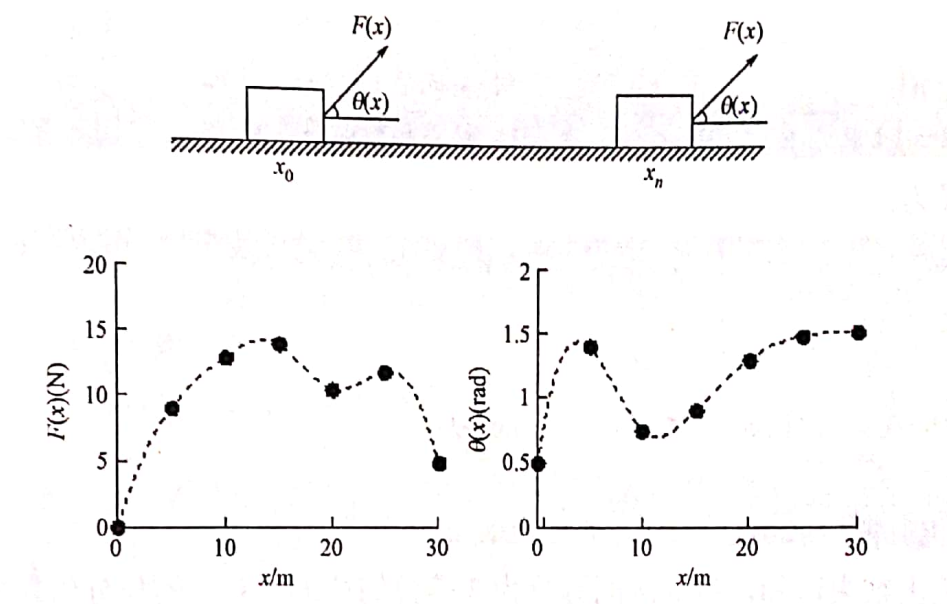

这里只有x=5m的离散测量值，如表所示

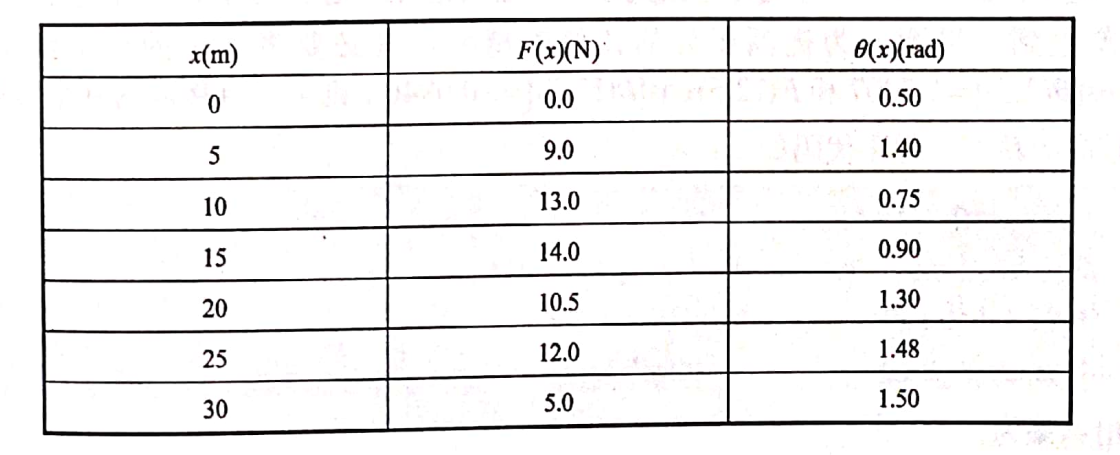

求解这一过程中$F\left(x\right)$做功$W$。

x=0:5:30;
theta=[0.50 1.40 0.75 0.90 1.30 1.48 1.50];
F=[0 9 13 14 10.5 12 5];
F_theta=F.*cos(theta);
xi=0:30;  % 将数据区间进行间距1m的采样以进行插值操作
thetai=spline(x,theta,xi);  % 对theta进行三次样条插值
Fi=spline(x,F,xi);  % 对F进行三次样条插值
F_thetai=Fi.*cos(thetai);
I_R=trape_quad(xi,F_thetai)  % 计算插值后的数值积分

I_R = 123.1755

n=[1 2 3 6];  % 区间等分数向量
for k=1:length(n)
    I(k)=trape_quad(x(1:n(k):end),F_theta(1:n(k):end));  % 求解各种情况下的积分值
end
I=fliplr(I)  % 将向量I反转

I =     5.3053  133.1907  124.9754  119.0892


err=abs(I-I_R)/I_R  % 计算相对误差

err =     0.9569    0.0813    0.0146    0.0332


**8.1.2 辛普森求积公式**

        在Newton-Cotes公式中取$n=2,x_0 =a,x_1 =\frac{a+b}{2},x_2 =b,\textrm{则有}$$A_0 =\frac{{\left(-1\right)}^2 h}{2!0!}\int_0^2 \left(t-1\right)\left(t-2\right)\textrm{dt}\;=\frac{b-a}{6}$，$A_1 =\frac{{\left(-1\right)}^1 h}{1!1!}\int_0^2 t\left(t-2\right)\textrm{dt}\;=\frac{4\left(b-a\right)}{6}$，$A_2 =\frac{{\left(-1\right)}^0 h}{2!0!}\int_0^2 t\left(t-1\right)\textrm{dt}\;=\frac{b-a}{6}$，`于是得到3个求积节点的插值型求积公式`


$$I_2 \left(f\right)=\frac{b-a}{6}f\left(x_0 \right)+\frac{4\left(b-a\right)}{6}f\left(x_1 \right)+\frac{b-a}{6}f\left(x_2 \right)=\frac{b-a}{6}\left\lbrack f\left(x_0 \right)+4f\left(x_1 \right)+f\left(x_2 \right)\right\rbrack$$


称

                                                                        
$$S\left(f\right)=\frac{b-a}{6}\left\lbrack f\left(a\right)+4f\left(\frac{a+b}{2}\right)+f\left(b\right)\right\rbrack$$
                                   
$$\left(8-8\right)$$


`为辛普森（Simpson）公式。`

`    可以证明，辛普森公式的误差为`$R_s \left(f\right)=-\frac{1}{90}{\left(\frac{b-a}{2}\right)}^5 f^{\left(4\right)} \left(\eta \right)\;\left(a<\eta <b\right)$。`同样地，由式`$\left(8-8\right)$`可知辛普森公式的代数精度为3。`

`    同梯形公式一样，实际中应用较多的仍然是复化辛普森公式。`

    把积分区间$\left\lbrack a,b\right\rbrack$分为n等份，分点为$x_k =a+\textrm{kh}\left(k=0,1,2,\ldotp \ldotp \ldotp ,n\right)$，其中$h=\frac{b-a}{n}$。记区间$\left\lbrack x_k ,x_{k+1} \right\rbrack$的中点为$x_{k+\frac{1}{2}}$，`在每个小区间`$\left\lbrack c,x_{k+1} \right\rbrack$`上利用辛普森公式，则有`$\int_a^b f\left(x\right)\textrm{dx}=\sum_{k=0}^{n-1} \frac{x_{k+1} -x_k }{6}\left\lbrack f\left(x_k \right)+4f\left(x_{k+\frac{1}{2}} \right)+f\left(x_{k+1} \right)\right\rbrack$，记

                                
$$S_n \left(f\right)=\int_a^b f\left(x\right)\textrm{dx}=\frac{h}{6}\left\lbrack f\left(a\right)+2\sum_{k=1}^{n-1} f\left(x_k \right)+4\sum_{k=0}^{n-1} f\left(x_{k+\frac{1}{2}} \right)+f\left(b\right)\right\rbrack$$
                                  
$$\left(8-9\right)$$


`公式`$\left(8-9\right)$`称为复化辛普森公式。`

`    显然公式`$\left(8-9\right)$`可以写为如下形式`$S_n \left(f\right)=\frac{h}{3}\left\lbrack \frac{f\left(a\right)+f\left(b\right)}{2}+\sum_{k=1}^{n-1} f\left(x_k \right)\right\rbrack +\frac{2h}{3}\sum_{k=0}^{n-1} f\left(x_{k+\frac{1}{2}} \right)=\frac{1}{3}T_n +\frac{2}{3}H_n$              $\left(8-10\right)$

其中$H_n =h\sum_{k=0}^{n-1} f\left(x_{k+\frac{1}{2}} \right)$。

        根据公式可以编写复化梯形求积的程序simpson.m，具体内容如下：

function I=simpson(fun,a,b,n,varargin)

% 复化辛普森公式求解数值积分(已知函数原型)

% 输入参数：

%      ---fun：被积函数

%      ---a,b：积分区间的端点

%      ---n：区间等间距分割区间的数目

%      ---：p1,p2,…：函数fun的附加参数

% 输出参数：

%      ---I：求得的积分值

if nargin<4|isempty(n)

    n=1e4;

end

h=(b-a)/n;

x=a+h*(0:n);

fx=feval(fun,x,varargin{:});

I=h*[fx(1)+fx(end)+2*sum(fx(2:end-1))+...

    4*sum(feval(fun,(x(1:end-1)+x(2:end))/2,varargin{:}))]/6;  % 公式8-11

`该函数的调用格式为：I=simpson(fun,a,b,p1,p2,...)`

`【例8-3】利用复化辛普森公式求解【例8-1】中的积分问题。`

v=simplify(dsolve('Dv=g-c_d/m*v^2','v(0)=0','t'))  % 微分方程解析解
f=eval(['@(t,g,m,c_d)',char(v)])  % 将符号表达式写成匿名函数
g=9.81;m=68.1;c_d=0.25;
v_3=subs(v,{'t','g','m','c_d'},{3,g,m,c_d})  % 第3秒的下降速度
x=simpson(@(t)f(t,g,m,c_d),0,3)  % 最初3秒内下降的高度
% x=simpson(f,0,3,[],g,m,c_d)

`    考虑到在每个小区间`$\left\lbrack x_k ,x_{k+1} \right\rbrack$`上利用辛普森公式时，还需要将子区间再二等分，因此有2n+1个分点，即实际上有`$x_k =a+k\frac{h}{2}\left(k=0,1,2,\ldotp \ldotp \ldotp ,2n\right)$，经推导得到$S_n \left(f\right)=\int_a^b f\left(x\right)\textrm{dx}=\frac{h}{6}\left\lbrack f\left(a\right)+2\sum_{k=1}^{n-1} f\left(x_{2k} \right)+4\sum_{k=0}^{n-1} f\left(x_{2k+1} \right)+f\left(b\right)\right\rbrack$                                                   $\left(8-11\right)$

`根据式`$\left(8-11\right)$`可以编写复化辛普森公式求解已知离散数据点的数值微分问题的程序simp_quad.m，具体内容如下：`

`function I=simp_quad(x,y)`

`% 复化辛普森公式求解数值积分(已知离散数据点)`

`% 输入参数：`

`%      ---x：被积函数自变量的等距节点`

`%      ---y：被积函数在节点处的函数值`

`% 输出参数：`

`%      ---I：求得的积分值`

`m=length(x);n=length(y);`

`if m~=n`

`    error('x和y的长度必须相等！')`

`end`

`if rem(n-1,2)~=0`

`    % 如果n-1不能被2整除，则调用复化梯形公式求解`

`    warning('此种情形不适合用Simpson公式，调用梯形公式求解');`

`    I=trape_quad(x,y);  % 调用复化梯形公式求解`

`    return;`

`end`

`N=(n-1)/2; h=(x(n)-x(1))/N;`

`a=[1,reshape([4*ones(1,N-1);2*ones(1,N-1)],1,[]),4,1];  % 公式8-11向量乘积的系数向量`

`I=h/6*a*y';  % 公式8-11的向量乘积形式`

`该函数的调用格式为：I=simp_quad(x,y)`

`【例8-4】利用复化辛普森公式求积分`$I=\int_{-1}^1 e^{-x^2 } \textrm{dx}$`，间隔取为0.1。`

`编写如下语句：`

x=-1:0.1:1;
y=exp(-x.^2); %计算函数值
I=simp_quad(x,y) %调用函数simp_quad求解

**8.1.3 Cotes公式**

        `在Newton-Cotes公式中取`$n=4,x_0 =a,x_1 =x_0 +h,x_2 =x_0 +2h,x_3 =x_0 +3h,x_4 =b$，则有$A_0 =A_4 =\frac{7}{90}\left(b-a\right),A_1 =A_3 =\frac{32}{90}\left(b-a\right),A_2 =\frac{12}{90}\left(b-a\right)$，故Cotes公式为


$$C\left(f\right)=\frac{b-a}{90}\left\lbrack 7f\left(a\right)+32f\left(\frac{3a+4}{b}\right)+12f\left(\frac{a+b}{2}\right)+32f\left(\frac{a+3b}{4}\right)+7f\left(b\right)\right\rbrack$$
                                               
$$\left(8-12\right)$$


`Cotes公式的误差为`$R_C \left(f\right)=-\frac{8}{945}{\left(\frac{b-a}{4}\right)}^7 f^{\left(6\right)} \left(\eta \right)\;\left(a<\eta <b\right)$，`由此可知，Cotes公式的代数精度为5。`

`    类似于复化梯形公式和复化辛普森公式的推导过程，可以得到复化Cotes公式：`


$$C_n \left(f\right)=\sum_{k=0}^{n-1} \frac{h}{90}\left\lbrack 7f\left(x_k \right)+32f\left(x_{k+\frac{1}{4}} \right)+12f\left(x_{k+\frac{1}{2}} \right)+32f\left(x_{k+\frac{3}{4}} \right)+7f\left(x_{k+1} \right)\right\rbrack$$
                                                
$$\left(8-13\right)$$


即$C_n \left(f\right)=\frac{h}{90}\left\lbrack 7f\left(a\right)+32\sum_{k=0}^{n-1} f\left(x_{k+\frac{1}{4}} \right)+12\sum_{k=0}^{n-1} f\left(x_{k+\frac{2}{4}} \right)+32\sum_{k=0}^{n-1} f\left(x_{k+\frac{3}{4}} \right)+14\sum_{k=1}^{n-1} f\left(x_k \right)+7f\left(b\right)\right\rbrack$                    $\left(8-14\right)$

`    根据式`$\left(8-12\right)$`可以编写复化Cotes公式求解数值积分的通用程序Cotes.m，具体内容为：`

`function I=Cotes(fun,a,b,n,varargin)`

`% 复化Cotes公式求解数值积分(已知函数原型)`

`% 输入参数：`

`%      ---fun：被积函数`

`%      ---a,b：积分区间的端点`

`%      ---n：区间等间距分割区间的数目`

`%      ---p1,p2,...：fun的附加参数`

`% 输出参数：`

`%      ---I：求得的积分值`

`if nargin<4|isempty(n);`

`    n=1e4;`

`end`

`h=(b-a)/n;`

`x=a+h*(0:n);`

`fx=feval(fun,x,varargin{:});`

`%I=h*[(7*fx(1)+7*fx(end))+32*sum(feval(fun,x(2:4:end),varargin{:}))+...`

`    %12*sum(feval(fun,x(3:4:end),varargin{:}))+...`

`    %32*sum(feval(fun,x(4:4:end),varargin{:}))+...`

`    %14*sum(feval(fun,x(5:4:end),varargin{:}))]/90;`

`I=h*[(7*fx(1)+7*fx(end))+32*sum(feval(fun,x(1:end-1)+1/4*h,varargin{:}))+...`

`    12*sum(feval(fun,x(1:end-1)+1/2*h,varargin{:}))+...`

`    32*sum(feval(fun,x(1:end-1)+3/4*h,varargin{:}))+...`

`    14*sum(feval(fun,x(1:end-1)+h,varargin{:}))]/90;  % 公式8-14`

`该函数的调用格式为：I=Cotes(fun,a,b,n,p1,p2,...)`

`【例8-5】用复化Cotes公式计算积分`$I=\int_1^5 \frac{\textrm{sinx}}{x}\textrm{dx}$的值。

`编写如下语句：`

f=@(x)sin(x)./x; %定义被积函数
I=Cotes(f,1,5) %Cotes法计算定积分

`与公的式`$\left(8-12\right)$`推导类似，可以得到`


$$C_n \left(f\right)=\frac{h}{90}\left\lbrack 7f\left(a\right)+32\sum_{k=0}^{n-1} f\left(x_{4k+1} \right)+12\sum_{k=0}^{n-1} f\left(x_{4k+2} \right)+32\sum_{k=0}^{n-1} f\left(x_{4k+3} \right)+14\sum_{k=1}^{n-1} f\left(x_{4k} \right)+7f\left(b\right)\right\rbrack$$
                                
$$\left(8-15\right)$$


`下面给出复化Cotes公式求解已知离散数据点的数值积分问题的程序cots_quad.m，` `具体内容如下：`

`function I=cotes_quad(x,y)`

`% 复化cotes公式求解数值积分(已知离散数据点)`

`% 输入参数：`

`%      ---x：被积函数自变量的等距节点`

`%      ---y：被积函数在节点处的函数值`

`% 输出参数：`

`%      ---I：求得的积分值`

`m=length(x);n=length(y);`

`if m~=n`

`    error('x和y的长度必须相等！')`

`end`

`if rem(n-1,4)~=0 `

`    % 如果n-1不能被4整除，则调用复化梯形公式`

`    warning('此种情形不适用于Cotes公式，调用复化梯形公式求解');`

`    I=trape_quad(x,y);`

`    return;`

`end`

`N=(n-1)/4; h=(x(n)-x(1))/N;`

`a=[7,reshape([32*ones(1,N-1);12*ones(1,N-1);...`

`    32*ones(1,N-1);14*ones(1,N-1)],1,n-5),32,12,32,7];`

`I=h/90*a*y';`

`该函数的调用格式为：I=cotes_quad(x,y)`

`【例8-6】利用复化Cotes公式求解【例8-4】。`

`编写如下语句：`

x=-1:0.1:1;
y=exp(-x.^2); %计算函数值
Icq=cotes_quad(x,y) %Cotes公式求解定积分

f=@(x)exp(-x.^2); %定义被积函数
Ic=Cotes(f,-1,1) %Cotes法计算定积分

### **8.2 自适应步长求积方法**

        `复化求积方法通常用于被积函数变化不太大的积分，如果在求积区间中被积函数变化很大，有的部分函数值变化剧烈，而有的部分变化平缓，这时统一将区间等分用复化求积方法计算积分工作量比较大，这是因为要达到误差要求对变化剧烈部分必须将区间细分而平缓部分则可用大步长。针对被积函数在区间上不同情形采用不同的步长，使得在满足精度前提下积分计算工作量尽可能小，对于这类问题的算法技巧是在不同区间上预测被积函数变化的剧烈程度，确定相应步长，这种方法称为自适应步长求积方法。`

**8.2.1 自适应步长梯形公式**

       将区间$\left\lbrack a,b\right\rbrack$$\;n$等分，步长$h_n =\frac{b-a}{n}$，`由复化梯形公式有：`

`在`$\left\lbrack x_k ,x_{k+1} \right\rbrack$上，$T_{1k} =\frac{h_n }{2}\left(f\left(x_k \right)+f\left(x_{k+1} \right)\right)$

在$\left\lbrack a,b\right\rbrack$上，$T\left(h_n \right)=T_n =\sum_{k=0}^{n-1} T_{1k} =\frac{h_n }{2}\left(f\left(a\right)+f\left(b\right)\right)+h_n \sum_{k=1}^{n-1} f\left(x_k \right)$

`将原n等分区间再次分半，在每个小区间`$\left\lbrack x_k ,x_{k+1} \right\rbrack$`上取中点`$x_{k+\frac{1}{2}}$，则分成两个小区间$\left\lbrack x_k ,x_{k+\frac{1}{2}} \right\rbrack$和$\left\lbrack x_{k+\frac{1}{2}} ,x_{k+1} \right\rbrack$，于是`等分数`$n$`变为`$2n$`，步长`$h_n$`，变为`$h_{2n} =\frac{h_n }{2}$。

`在`$\left\lbrack x_k ,x_{k+1} \right\rbrack$上，$T_{2k} =\frac{h_{2n} }{2}\left(f\left(x_k \right)+f\left(x_{k+\frac{1}{2}} \right)\right)+\frac{h_{2n} }{2}\left(f\left(x_{k+\frac{1}{2}} \right)+f\left(x_{k+1} \right)\right)=\frac{1}{2}T_{1k} +\frac{h_n }{2}f\left(x_{k+\frac{1}{2}} \right)$

在$\left\lbrack a,b\right\rbrack$上，$T\left(\frac{h_n }{2}\right)=T_{2n} =\sum_{k=0}^{n-1} T_{2k} =\frac{1}{2}T_n +\frac{h_n }{2}\sum_{k=0}^{n-1} f\left(x_{k+\frac{1}{2}} \right)=\frac{1}{2}T_n +\frac{H_n }{2}$

`由此得到自适应步长梯形公式的递推公式`$T_{2n} =\frac{1}{2}T_n +\frac{H_n }{2}$                                        $\left(8-16\right)$

`实际计算中的递推公式为`


$$\left\lbrace \begin{array}{cc}
T_1 =\frac{b-a}{2}\left\lbrack f\left(a\right)+f\left(b\right)\right\rbrack  & \\
T_{2n} =\frac{1}{2}T_n +\frac{b-a}{2n}\sum_{j=0}^{n-1} f\left(a+\left(2j+1\right)\frac{b-a}{2n}\right) & \left(n=1,2,\ldotp \ldotp \ldotp \right)
\end{array}\right.$$
                                
$$\left(8-17\right)$$


直到$\left|T_{2n} -T_n \right|\le \varepsilon$为止，$T_{2n}$作为积分的近似值。

`下面给出自适应步长梯形公式求解数值微分问题的通用程序adapt_trape.m，具体内容如下：`

`function I=adapt_trape(fun,a,b,eps,varargin)`

`% 自适应梯形公式求解数值积分`

`% 输入参数：`

`%      ---fun：被积函数`

`%      ---a,b：积分区间的端点`

`%      ---eps：精度要求，默认值为1e-6`

`%      ---p1,p2,...：fun的附加参数`

`% 输出参数：`

`%      ---I：求得的积分值`

`if nargin<4|isempty(eps);`

`    eps=1e-6;`

`end`

`N=1;h=b-a;`

`T=h/2*sum(feval(fun,[a,b],varargin{:}));`

`tol=1;`

`while tol>eps`

`    h=h/2;I=T/2;`

`    x=a+(2*(1:N)-1)*h;`

`    fx = feval(fun,x,varargin{:}); % 计算函数值`

`    I=I+h*sum(fx);`

`    tol=abs(I-T);`

`    N=N*2; T=I;`

`end`

`该函数的调用格式为：I=adapt_trape(fun,a,b,eps,pl,p2,...)`

`【例8-7】利用自适应步长梯形公式求解【例8-5】。`

`编写如下语句：`

f=@(x)sin(x)./x %定义被积函数
I=adapt_trape(f,1,5) %自适应梯形法求定积分

**8.2.2 自适应步长辛普森公式**

`由(8-11)和(8-16)可解得`$S_n =\frac{1}{3}T_n +\frac{2}{3}\left(2T_{2n} -T_n \right)=\frac{1}{4^1 -1}$$\left({4^1 T}_{2n} -T_n \right)$                                     $\left(8-18\right)$

`式(8-18)` `即为自适应步长辛普森公式。由该式可知，` `不必直接给出Simpson求积法的递推公式，它的计算可由梯形递推公式得到。`

`下面给出自适应步长辛普森公式通用MATLAB程序adapt_simp.m，内容如下：`

`function I=adapt_simp(fun,a,b,eps,varargin)`

`% 自适应辛普森公式求解数值积分`

`% 输入参数：`

`%      ---fun：被积函数`

`%      ---a,b：积分区间的端点`

`%      ---eps：精度要求，默认值为1e-6`

`%      ---p1,p2,...：fun的附加参数`

`% 输出参数：`

`%      ---I：求得的积分值`

`if nargin<4|isempty(eps);`

`    eps=1e-6;`

`end`

`N=1;h=b-a;`

`T=h/2*sum(feval(fun,[a,b],varargin{:}));`

`tol=1;S=T;`

`while tol>eps`

`    h=h/2;T1=T/2;`

`    x=a+(2*(1:N)-1)*h;`

`    fx = feval(fun,x,varargin{:}); % 计算函数值`

`    T1=T1+h*sum(fx);`

`    I=(4*T1-T)/3;`

`    tol=abs(I-S);`

`    N=N*2;T=T1;S=I;`

`end`

`该函数的调用格式为：`

`I=adapt_simp(fun,a,b,eps,p1,p2,...)`

`【例8-8】利用自适应步长梯形公式求解【例8-5】，取精度要求为`$\varepsilon ={10}^{-5}$。

`编写如下语句：`

f=@(x,a)sin(x)./x; %定义被积函数
I=adapt_simp(f,1,5)  %自适应步长辛普森法计算定积分

**8.2.3 自适应步长Cotes公式**

`与推导自适应步长辛普森公式递推公式的过程类似，可以得到`$C_n =\frac{4^2 S_{2n} -S_n }{4^2 -1}$                              $\left(8-19\right)$

`式(8-19)` `称为自适应步长Cotes公式，通常自适应步长Cotes公式优于自适应步长辛普森公式。`

`下面给出自适应步长Cotes公式的通用程序adapt_Cotes.m，内容如下：`

`function I=adapt_Cotes(fun,a,b,eps,varargin)`

`% 自适应Cotes公式求解数值积分`

`% 输入参数：`

`%      ---fun：被积函数`

`%      ---a,b：积分区间的端点`

`%      ---eps：精度要求，默认值为1e-6`

`%      ---p1,p2,...：fun的附加参数`

`% 输出参数：`

`%      ---I：求得的积分值`

`if nargin<4|isempty(eps);`

`    eps=1e-6;`

`end`

`N=1;h=b-a;`

`T=h/2*sum(feval(fun,[a,b],varargin{:}));`

`tol=1;C=T;`

`while tol>eps`

`    h=h/2;T1=T/2;`

`    x=a+(2*(1:N)-1)*h;`

`    fx = feval(fun,x,varargin{:}); % 计算函数值`

`    T1=T1+h*sum(fx);`

`    T2=(4*T1-T)/3;`

`    I=(16*T2-T1)/15;`

`    tol=abs(I-C);`

`    N=N*2;T=T1;T1=T2;C=I;`

`end`

`end`

`该函数的调用格式为：I=adapt_Cotes(fun,a,b,eps,p1,p2,...)`

`【例8-9】已知阻尼正弦波函数为`$f\left(t,\xi \right)=\frac{e^{-\xi t} }{\cos \alpha }\cos \left(t\sqrt{1-\xi^2 }+\alpha \right)$，其中$\alpha =\arctan \frac{-\xi }{\sqrt{1-\xi^2 }}$，`试求积分`$I=\int_0^{20} f\left(t,0\ldotp 1\right)\textrm{dt}$。

`首先编写如下被积函数描述文件Dampedsinewave.m，程序如下：`

`function f=Dampedsinewave(t,xi)`

`alpha=atan(-xi/sqrt(1-xi^2)); %计算alpha`

`f=exp(-xi*t).*cos(t*sqrt(1-xi^2) +alpha)/cos(alpha) %求函数值`

`end`

`再编写如下主程序:`

format long
xi=0.1;
I=adapt_Cotes(@Dampedsinewave,0,20,[],xi)  %数值解

**8.2.4 Romberg求积公式**

`由式(8-16)、式(8-18)和式(8-19)可知，复化梯形公式的线性组合可以得到复化辛普森公式，而复化辛普森公式通常优于复化梯形公式：进一步，复化辛普森公式的线性组合可以得到复化Cotes公式，` `而Cotes公式一般优于辛普森公式。``将复化``Cotes``公式进行如下形``式的线性组合：`

                                                                                                   
$$R_n =\frac{4^3 C_{2n} -C_n }{4^3 -1}$$
                                      
$$\left(8-20\right)$$


`称式(8-20)` `为Romberg公式。可以推断，` `Romberg公式应该优于Cotes公式，` `按照这种方法做下去，` `能够得到收敛很好的计算公式，` `这就是Romberg求积公式的基本思想。``其一般计算公式为`$\left\lbrace \begin{array}{cc}
T_1^{i+1} =\frac{1}{2}T_1^i +\frac{h}{2}\sum_{k=0}^{n-1} f\left(x_{k+\frac{1}{2}} \right) & \\
T_{j+1}^{i+1} =\frac{4^j T_j^{i+1} -T_j^i }{4^j -1} & 
\end{array}\right.$                               $\left(8-21\right)$

`式(8-21) 也称为Richardson外推加速公式。`

`Romberg积分法的思想可以理解为不断对分分割步长，并累加增加的采样点函数值。下面给出Romberg积分法的实现程序Romberg.m，` `内容如下：`

`function [I,T]=Romberg(fun,a,b,eps,varargin)`

`% Romberg公式求解数值积分`

`% 输入参数：`

`%      ---fun：被积函数`

`%      ---a,b：积分区间的端点`

`%      ---eps：精度要求，默认值为1e-6`

`%      ---p1,p2,...：fun的附加参数`

`% 输出参数：`

`%      ---I：求得的积分值`

`%      ---T：Romberg积分过程产生的下三角阵`

`if nargin<4|isempty(eps);`

`    eps=1e-6;`

`end`

`N=1;h=b-a;`

`T(1,1)=h/2*sum(feval(fun,[a,b],varargin{:}));`

`tol=1;`

`while tol>eps`

`    h=h/2;N=2*N;k=log2(N);`

`    x=a+(2*(1:N/2)-1)*h;`

`    fx = feval(fun,x,varargin{:}); % 计算函数值`

`    T(k+1,1)=1/2*T(k,1)+h*sum(fx);`

`    for j=1:k`

`        T(k+1,j+1)=(4^j*T(k+1,j)-T(k,j))/(4^j-1);`

`    end`

`    tol=abs(T(k+1,k+1)-T(k,k));`

`end`

`I=T(k+1,k+1);`

`end`

`该函数的调用格式为：[I,T]=Romberg(fun,a,b,eps,p1,p2,...)`

`【例8-10】利用Romberg求积公式求解【例8-9】。`

`编写如下语句：`

xi=0.1;
[I,T]=Romberg(@Dampedsinewave,0,20,[],xi)

测试：

2.03 * 4 / 3 - 10.79 / 3

0.384 * 16 / 15 + 0.894 / 15

0.3019 * 4 / 3 - 0.3012 / 3

### **8.3 Gauss求积方法**

        `在``Newton-Cotes``公式``(8-3)` `中，要求节点是等间距的，其代数精度依赖于节点个数`$n$`，当`$n$`为奇数时，求积公式具有`$n$`阶代数精度；当`$n$`为偶数时，求积公式具有`$n+1$`阶代数精度。在实际中，节点的无限增加会减弱求积公式的稳定性，且当`$n\to \infty$`时，`$\sum_{k=0}^n A_k f\left(x_k \right)$`不一定收敛于积分`$\int_a^b f\left(x\right)\textrm{dx}$`的值。那么，能否通过节点的适当选择提高插值型求积公式的代数精度呢``?``这就是高斯求积所要解决的问题。`

**8.3.1 Gauss求积公式的构造**

`    由Newton-Cotes求积公式`$I_n \left(f\right)=\int_a^b f\left(x\right)\textrm{dx}=\sum_{k=0}^n A_k f\left(x_k \right)$                                          $\left(8-22\right)$

`可知，节点`$x_k =a+\textrm{kh}\left(k=0,1,2,\ldotp \ldotp \ldotp ,n\right)$`是等间距的，也是确定的，`$A_k$`为待定参数。``现在不固定`$x_k$`，即把它也看成待确定参数，这样式``(8-22)``就可能对``2n+1``次多项式精确成立，即对`$f\left(x\right)=1,x,x^2 ,\ldotp \ldotp \ldotp ,x^{2n+1}$`精确。``至于系数`$A_k$`和节点`$x_k$`可以通过方程组的相关知识求解。`


$$\int_{-1}^{1}f(x)dx = f(\frac{1}{\sqrt{3}})+f(-\frac{1}{\sqrt{3}})$$


`上述构造Gauss``求积公式的方法称为待定系数法，除此之外，``还可以利用正交多项式构造高斯求积公式，下面简要介绍。`

`    设`$P_n \left(x\right)\left(n=0,1,2,\ldotp \ldotp \ldotp \right)$`为正交多项式序列，`$P_n \left(x\right)$`具有如下性质:`

`对每个`$n$`，`$P_n \left(x\right)$`是`$n$`次多项式；`

`正交性：`$\int_a^b \rho \left(x\right)P_i \left(x\right)P_j \left(x\right)\textrm{dx}=0,\left(i\not= j\right)$；

`对任意一个次数不大于n-1的多项式`$P\left(x\right)$`，有`$\int_a^b \rho \left(x\right)P\left(x\right)P_n \left(x\right)\textrm{dx}=0,n\ge 1$

$P_n \left(x\right)$`在`$\left\lbrack a,b\right\rbrack$`内有`$n$`个互异零点。`

`这样可以得到如下定理：设`$x_0 ,x_1 ,\ldotp \ldotp \ldotp ,x_n$`是`$n+1$`次正交多项式`$P_{n+1} \left(x\right)$`的`$n+1$`个互异零点，则插值型求积公式`$\int_a^b \rho \left(x\right)f\left(x\right)\textrm{dx}\approx \sum_{k=0}^n A_k f\left(x_k \right)$`即是Gauss型求积公式。其中`$A_k =\int_a^b \rho \left(x\right)\prod_{i=0,i\not= k}^n \frac{x-x_i }{x_k -x_i }\textrm{dx}$

**8.3.2 几个常用的Gauss求积公式**

`    1.Gauss-Legendre求积公式`

`    勒让德(Legendre) 多项式`$P_{n+1} \left(x\right)=\frac{1}{2^{n+1} \left(n+1\right)!}\frac{d^{n+1} }{dx^{n+1} }{\left(x^2 -1\right)}^{n+1}$`是区间[-1,1]上关于权函数`$\rho \left(x\right)=1$`的正交多项式，取`$P_{n+1} \left(x\right)$`的`$n+1$`个根作为求积节点，则得到Gauss-Legendre求积公式`$\int_{-1}^1 f\left(x\right)\textrm{dx}\approx \sum_{k=0}^n A_k f\left(x_k \right)$                                    $\left(8-23\right)$

其中$A_k =\int_{-1}^1 \frac{P_{n+1} \left(x\right)}{\left(x-x_k \right){P^{\prime } }_{n+1} \left(x_k \right)}\textrm{dx}=\frac{2}{\left(1-x_k^2 \right){\left\lbrack {P^{\prime } }_{n+1} \left(x_k \right)\right\rbrack }^2 }$

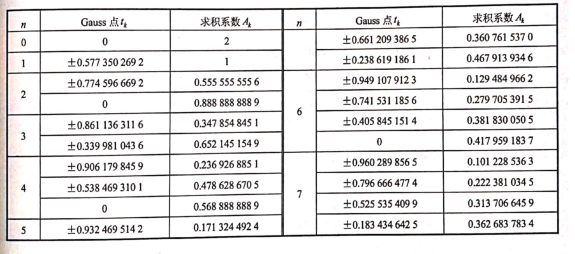

`Gauss-Legendre求积公式的程序Gauss_legendre.m，内容如下：`

`function I=Gauss_legendre(fun,a,b,m,n,varargin)`

`% Gauss公式求解数值积分`

`% 输入参数：`

`%      ---fun：被积函数`

`%      ---a,b：积分区间的端点`

`%      ---m：每段Gauss点数`

`%      ---n：等分区间数`

`%      ---p1,p2,...：fun的附加参数`

`% 输出参数：`

`%      ---I：求得的积分值`

`if nargin<5|isempty(n);`

`    n=10;`

`end`

`switch m`

`    case 0`

`        t=0;A=2;`

`    case 1`

`        t=[-0.5773502692,0.5773502692];A=[1,1];`

`    case 2`

`        t=[-0.7745966692,0,0.7745966692];`

`        A=[0.5555555556,0.8888888889,0.5555555556];`

`    case 3`

`        t=[-0.8611363116,-0.3399810436,0.3399810436,0.8611363116];`

`        A=[0.3478548451,0.6521451549,0.6521451549,0.3478548451];`

`    case 4`

`        t=[-0.9061798459,-0.5384693101,0,0.5384693101,0.9061798459];`

`        A=[0.2369268851,0.4786286705,0.5688888889,0.4786286705,0.2369268851];`

`    case 5`

`        t=[-0.9324695142,-0.6612093865,-0.2386191861,...`

`            0.2386191861,0.6612093865,0.9324695142];`

`        A=[0.1713244924,0.3607615370,0.4679139346...`

`            0.4679139346,0.3607615370,0.1713244924];`

`    case 6`

`        t=[-0.9491079123,-0.7415311856,-0.4058451514,0,...`

`            0.4058451514,0.7415311856,0.9491079123];`

`        A=[0.1294849662,0.2797053915,0.3818300505,0.4179591837,...`

`            0.3818300505,0.2797053915,0.1294849662];`

`    case 7`

`        t=[-0.9602898565,-0.7966664774,-0.5255354099,0.1834346425,...`

`            0.1834346425,0.5255354099,0.7966664774,0.9602898565];`

`        A=[0.1012285363,0.2223810345,0.3137066459,0.3626837834...`

`            0.3626837834,0.3137066459,0.2223810345,0.1012285363,];`

`    otherwise`

`        error('本程序最多仅提供m=7！')`

`end`

`h=(b-a)/n;I=0;`

`for k=1:n`

`    F=feval(fun,h/2*t+a+(k-1/2)*h,varargin{:});`

`    I=I+A*F';`

`end`

`I=h/2*I;`

`end`

`该函数的调用格式为：I=Gauss_legendre(fun,a,b,m,n,p1,p2,...)`

`【例8-11】 利用Gauss-Legendre求积公式求解【例8-5】`

syms x;
format short e
f=@(x) sin(x)./x; %定义被积函数
for m=1:6
I=Gauss_legendre(f,1,5,m); %Gauss-Legendre公式求积分
err(m) =abs(I-double(int(sin(x)/x,1,5))); %计算绝对误差
end
err %显示误差结果

`    2.Gauss-Lobatto求积公式`

`    Gauss-Lob``at``to求积公式是Gauss-Legendre求积公式的一种修正，它是将区间的两个端点固定，其余的`$n-1$`个插值节点可以自由调整，因Gauss-Lob``at``to求积公式具有`$2n-1$`阶代数精度。`

`    设`$f\left(x\right)\in C\left\lbrack -1,1\right\rbrack$，`则Gauss-Lobatto求积公式为`$\int_{-1}^1 f\left(x\right)\textrm{dx}\approx \frac{2}{n\left(n+1\right)}\left\lbrack f\left(1\right)+f\left(-1\right)\right\rbrack +\sum_{k=1}^{n-1} A_k f\left(x_k \right)$           $\left(8-24\right)$

式中$x_k$为$P_{n-1}^‘ \left(x\right)=0$的根，$P_{n-1} \left(x\right)$`为`$n-1$`阶勒让德多项式。且`$A_k =\frac{2}{n\left(n-1\right){\left\lbrack P_{n-1} \left(x_k \right)\right\rbrack }^2 }$

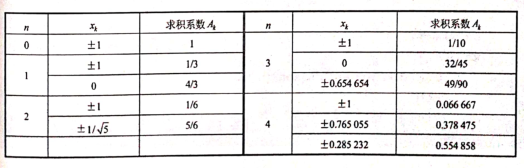    

`Gauss-Lobatto求积公式的程序Gauss_Lobatto.m，内容如下:`

`function I=Gauss_Lobatto(fun,a,b,m,n,varargin)`

`% Gauss_Lobatto公式求解数值积分`

`% 输入参数：`

`%      ---fun：被积函数`

`%      ---a,b：积分区间的端点`

`%      ---m：每段Gauss点数`

`%      ---n：等分区间数`

`%      ---p1,p2,...：fun的附加参数`

`% 输出参数：`

`%      ---I：求得的积分值`

`if nargin<5|isempty(n);`

`    n=10;`

`end`

`switch m`

`    case 0`

`        t=[-1,1];A=[1,1];`

`    case 1`

`        t=[-1,0,1];A=[1/3,4/3,1/3];`

`    case 2`

`        t=[-1,-1/sqrt(5),1/sqrt(5),1];`

`        A=[1/6,5/6,5/6,1/6];`

`    case 3`

`        t=[-1,-0.654654,0,0.654654,1];`

`        A=[1/10,49/90,32/45,49/90,1/10];`

`    case 4`

`        t=[-1,-0.765055,-0.285232,0.285232,0.765055,1];`

`        A=[0.066667,0.378475,0.554858,0.554858,0.378475,0.066667];`

`    otherwise`

`        error('本程序最多仅提供m=4！')`

`end`

`h=(b-a)/n;I=0;`

`for k=1:n`

`    F=feval(fun,h/2*t+a+(k-1/2)*h,varargin{:});`

`    I=I+A*F';`

`end`

`I=h/2*I;`

`该函数的调用格式为：I=Gauss_Lobatto(fun,a,b,m,n,p1,p2,...)`

` 【例8-12】利用Gauss-Lobat``to求积公式求解【例8-5】。`

syms x;
format short e
f=@(x)sin(x) ./x; %定义被积函数
for m=1:4
I=Gauss_Lobatto(f,1,5,m); %Gauss_Lob at to公式求积 
err(m)=abs(I-double(int(sin(x)/x,1,5))); %绝对误差
end
err   %显示误差结果

### **8.4 特殊函数的积分**

**8.4.1 震荡函数的积分**

`    工程问题中有时要计算如下形式的积分：`

$I_C \left(f\right)=\int_a^b f\left(x\right)\cos \omega \textrm{xdx}$和$I_S \left(f\right)=\int_a^b f\left(x\right)\sin \omega \textrm{xdx}$，其中$a=0,b=2\pi$。当$\omega$很大时，$\cos \omega x$和$\sin \omega \mathrm{x}$在区间$\left(a,b\right)$内与x轴有很多个交点。`相应的，` `当``ω``很大时，`$f\left(x\right)\cos \omega \mathrm{x}$`与`$f\left(x\right)\cos \omega \mathrm{x}$在区间$\left(a,b\right)$内与$x$轴也有很多个交点`，称上述积分为振荡函数的积分。`

`【例8-13】求解下面振荡函数的积分。`$I\left(f\right)=\int_0^{\pi } e^x \textrm{cos1000xdx}$

format long
f=@(x)exp(x).*cos(1000*x); %定义被积函数
I_trape=trape(f,0,pi,1000) %复化梯形求积

I_trape =      5.462992443166432e-05


I_simpson=simpson(f,0,pi,1000) %复化辛普森求积

I_simpson =      1.820997484319636e-05


I_legendre=Gauss_legendre(f,0,pi,ceil(6*rand),1000) %高斯-勒让德求积

I_legendre =      2.214067050389734e-05


syms x;
expr = exp(x) * cos(1000 * x);
F = int(expr,[0  pi])

$$F = \frac{{\mathrm{e}}^{\pi }}{1000001}-\frac{1}{1000001}$$

vpa(F)

$$ans = 0.000022140670492108776896952189415759$$

**8.4.2 反常（广义）积分**

`1.无界函数的反常积分`

`无界函数反常积分的定义：设函数`$f\left(x\right)$`在区间`$\left\lbrack a,b\right)$`上连续，`$b$`为奇点，若对`∀$\varepsilon >0$且$b-\varepsilon >a$，称极限$\lim_{\varepsilon \to 0^+ } \int_a^{b-\varepsilon } f\left(x\right)\textrm{dx}$                  $\left(8-25\right)$

为`无界函数`$f\left(x\right)$`在`$\left\lbrack a,b\right)$`上的反常积分(或瑕积分)，记为`$\int_a^b f\left(x\right)\textrm{dx}$。`对于瑕积分的求解比较简单，基本上可以使用前面介绍的数值方法求解，只是需要去掉相应的奇点即可。`

`【例8-14】计算瑕积分`$I=\int_0^1 \frac{1}{\sqrt{x}\left(e^x +1\right)}\textrm{dx}$

f=@(x)1./(sqrt(x).*(exp(x) +1)); %定义被积函数
I=Gauss_legendre(f,0,pi,4,1e5) %利用高斯-勒让德公式求奇异积分

I =    1.050585007009430


`2.无穷区间上的反常积分`

`设对任何大于`$a$`的实数`$b$`，`$f\left(x\right)$`在`$\left\lbrack a,b\right\rbrack$`上均可积，则称极限`$\lim_{b\to +\infty } \int_a^b f\left(x\right)\textrm{dx}$`为f(x)在无穷区间[a,+∞)上的反常积分，记为`$\int_a^{+\infty } f\left(x\right)\textrm{dx}$

`对于无穷区间上的反常积分通常有两种解决方法，下面分别介绍。`

`（1）无穷区间逼近`

`为叙述方便，仅考虑积分`$\int_0^{+\infty } f\left(x\right)\textrm{dx}$`的求解，由于`$\int_0^{+\infty } f\left(x\right)\textrm{dx}\lim_{b\to +\infty } \int_0^b f\left(x\right)\textrm{dx}$，因此取$0<b_0 <b_1 <\ldotp \ldotp \ldotp <b_n <\ldotp \ldotp \ldotp$且$b_n \to +\infty \left(n\to +\infty \right)$，有


$$\int_0^{+\infty } f\left(x\right)\textrm{dx}=\int_0^{b_0 } f\left(x\right)\textrm{dx}\int_{b_0 }^{b_1 } f\left(x\right)\textrm{dx}+\ldotp \ldotp \ldotp +\int_{b_n }^{b_{n+1} } f\left(x\right)\textrm{dx}+\ldotp \ldotp \ldotp$$
                              
$$\left(8-26\right)$$


`式``(8-26)``中的每个积分都是正常积分，利用前面介绍的方法求解。当`$\left|\int_{b_n }^{b_{n+1} } f\left(x\right)\textrm{dx}\right|\le \varepsilon$`时停止计算。`

`说明：终止准则`$\left|\int_{b_n }^{b_{n+1} } f\left(x\right)\textrm{dx}\right|\le \varepsilon$`仅是一个使用准则，在理论上并不是很确切。`

`根据上述求解过程可以编写相应的求解程序quad_inf.m，内容如下：`

`function I=quad_inf(fun,a,b,tol,eps)`

`% 无穷区间的积分`

`% 输入参数：`

`%       ---fun：被积函数`

`%       ---a,b：积分区间的端点，要求a<b`

`%       ---tol：精度要求，用于正常积分，缺省值为1e-6`

`%       ---eps：精度要求，迭代终止准则，缺省值为1e-5`

`% 输出参数：`

`%       ---I：求得的积分值`

`if nargin<5|isempty(eps);eps=1e-5;end;`

`if nargin<4|isempty(tol);tol=1e-6;end;`

`N=2;I=0;T=1;`

`if isinf(a)&isinf(b)`

`    I=quad_inf(fun,-inf,0)+quad_inf(fun,0,inf);  % 递归调用`

`elseif isinf(b)`

`    while T>eps`

`        b=a+N;`

`        T=quadl(fun,a,b,tol);`

`        I=I+T;`

`        a=b; N=2*N;`

`    end`

`elseif isinf(a)`

`    while T>eps`

`        a=b-N;`

`        T=quadl(fun,a,b,tol);`

`        I=I+T;`

`        b=a; N=2*N;`

`    end`

`else`

`    I=quadl(fun,a,b,tol);`

`end`

`该函数的调用格式为：I=quad_inf(fun,a,b,tol,eps)`

`【例8-15】计算无穷积分`$I=\int_0^{\infty } e^{-x^2 } \textrm{dx}$

f=@(x)exp(-x.^2); %定义被积函数
I=quad_inf(f,0,inf) %求无穷积分

I =    0.886227674998196


（2）变量替换

`【例8-16】利用变量替换求解【例8-15】`

`首先用变量替换`$t=\frac{x}{1+x}\left(x=\frac{t}{1-t},\textrm{dx}=\frac{1}{{\left(1-t\right)}^2 }\textrm{dt}\right)$`将区间`$\left\lbrack 0,+\infty \right)$`变换到区间`$\left\lbrack 0,1\right\rbrack$`，则有`$I=\int_0^1 e^{{-\left(\frac{t}{1-t}\right)}^2 } \frac{1}{{\left(1-t\right)}^2 }\textrm{dt}$

f=@(x)exp(-(x./(1-x)).^2)./(1-x).^2; %定义被积函数
I=simpson(f,eps,1-eps) %复化辛普森公式求积分

`说明：在上述语句中利用了MATLAB常量eps，` `它的数值是2.2204e-016，它避免了结果出现NaN或Inf的情形。``由上述输出结果可见，该题利用变量替换得到了满意的结果。`

**8.4.3 重积分的近似计算**

`在微积分中，重积分的计算是用化为累次积分的方法进行的。计算重数值积分也同样采用累次积分的计算过程。由于重积分的求解过程类似，故在此仅以二重积分为例进行说明。`

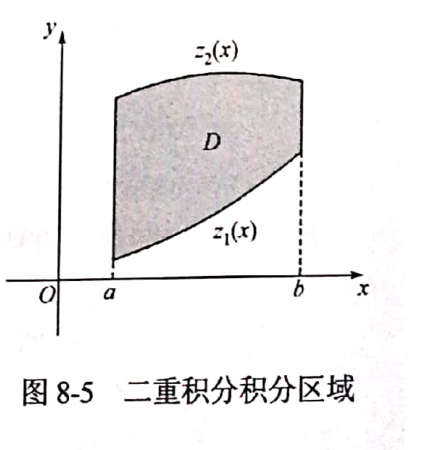

`对于二重积分`$\int \int_D f(x,y) \,dx\,dy$，可化为累次积分$\int_a^b \int_{z_1 \left(x\right)}^{z_2 \left(x\right)} f\left(x,y\right)\textrm{dydx}$                           $\left(8-27\right)$

`下面利用梯形法先将区间`$\left\lbrack a,b\right\rbrack \;m$`等分，并令`$h_x =\frac{b-a}{m},x_i =a+\textrm{ih}\left(i=0,1,2,\ldotp \ldotp \ldotp ,m\right)$，则$I\approx h_x \left(\frac{G\left(a\right)+G\left(b\right)}{2}+\sum_{i=1}^{m-1} G\left(x_i \right)\right)$，其中$G\left(x_i \right)=\int_{z_1 \left(x_i \right)}^{z_2 \left(x_i \right)} f\left(x_i ,y\right)\textrm{dy}$。再将$\left\lbrack z_1 \left(x_i \right),z_2 \left(x_i \right)\right\rbrack \textrm{区间n等分}$，令$h_y \left(i\right)=\frac{z_1 \left(x_i \right)-z_2 \left(x_i \right)}{n}$，因此$y_{\textrm{ij}} =z_1 \left(x_i \right)+jh_y \left(i\right)\left(i=0,1,\ldotp \ldotp \ldotp ,m;j=0,1,\ldotp \ldotp \ldotp ,n\right)$

进而有$G\left(x_i \right)\approx h_y \left(i\right)\left(\frac{f\left(x_i ,z_1 \left(x_i \right)\right)+f\left(x_i ,z_2 \left(x_i \right)\right)}{2}+\sum_{j=1}^{n-1} f\left(x_i ,y_{\textrm{ij}} \right)\right)$

`根据上述过程可以编写一般二重积分的数值求解程序double_integra.m，具体内容如下：`

`function I=double_integral(fun,a,b,lowfun,upfun,m,n,varargin)`

`% 一般形式的二重积分数值求解`

`% 输入参数：`

`%       ---fun：被积函数(是二维函数)`

`%       ---a,b,lowfun,upfun：积分区域，lowfun,upfun是x的函数`

`%       ---m：[a,b]区间的等分数`

`%       ---n：[lowfun,upfun]区间等分数`

`%       ---p1,p2,...：fun、lowfun、upfun的附加参数`

`% 输出参数：`

`%       ---I：积分值`

`if nargin<7|isempty(n),n=100;end`

`if nargin<6|isempty(m),m=100;end`

`hx=(b-a)/m;`

`x=a+(0:m)*hx;`

`for i=1:m+1`

`    ylow= feval(lowfun,x(i));`

`    yup=feval(upfun,x(i));`

`    hy=(yup - ylow)/n;`

`    y(i,:)=ylow+(0:n)*hy;`

`    f(i,:)=feval(fun,x(i),y(i,:));`

`    G(i)=trapz(y(i,:),f(i,:));`

`end`

`I=trapz(x,G);`

`end`

`该函数的调用格式为：I=double_integral(fun,a,b,lowfun,upfun,m,n,p1,p2,...)`

`【例8-17】利用上述方法求解如下二重定积分。`$I=\int \int_D (x+y+x^3e^y) \,dx\,dy$`其中`$D$`是下半圆域`$\left\lbrace \left(x,y\right)\left|x^2 +y^2 \le 4,y\le 0\right.\right\rbrace$`。`

`考虑到积分区域是关于`$y$`轴对称的，对于自变量`$x$`，`$x+x^3 e^y$`是奇函数，`$y$`可视为关于`$x$`的偶函数，因而`


$$I=\int \int_D (x+y+x^3e^y) \,dx\,dy=\int \int_D y \,dx\,dy$$

$$=2\int_0^2 \textrm{dx}\int_{-\sqrt{4-x^2 }}^0 \textrm{ydy}$$


fun=@(x,y)y*ones(size(x)); %被积函数
lowfun=@(x)-sqrt(4-x.^2); %内部积分积分下限
upfun=@(x)zeros(size(x)); %内部积分积分上限
I=2*double_integral(fun,0,2,lowfun,upfun) %计算二重积分

I =   -5.333200000000000


### **8.5 数值积分的MATLAB函数求解**

`虽然前面介绍的自编``MATLAB``函数能够求解一般的数值积分，但是也有其一定的局限性，幸好MATLAB自身也提供了好多求解数值积分的专用函数，比如trapz()函数，quad()函数，quadl()函数等。`

**8.5.1 trapz()函数**

`MATLAB中的trapz()函数是基于复化梯形公式设计编写的，其一般调用格式为：I=trpaz(x,y,dim)，其中``x，y``是观测数据，x``可以为行向量或列向量，``y``可以为向量或矩阵，``y``的行数应等于``x``向量的元素个数；dim``表示按维进行求积，若``dim=1(``默认值)，则按行求积，若``dm=2``，则按列求积。`

`【例8-18】利用trapz()函数求解积分`$\int_0^{\frac{3\pi }{2}} \textrm{cos15xdx}$`，选取步长为0.0001。`

h=0.0001;
x=[0:h:3*pi/2];y=cos(15*x);
I=trapz(x,y) %梯形法求积分

I = 0.0667

**8.5.2 quad()函数**

`前面已经介绍了利用自适应辛普森法求解数值积分，而MATLAB提供的quad()函数也是基于自适应辛普森法设计的，该函数的调用格式为：`

`[q,fcnt] ``=quad(fun,a,b,to``l,trace,p``1,p2,...)`

`其中fun是被积函数，可以是字符表达式、内联函数、匿名函数和Ｍ函数;a,b是定积分的上限和下限；``to``l为指定的误差限，默认值为`${10}^{-6}$`；trace提供中间输出[fcnt ab-aq]``，若trace=[]，则quad不提供中间输出；pl，p2...是函数fun的附加参数。q是返回的数值积分；fcnt是返回函数评估的次数。`

`【例8-19】利用quad()函数求解【例8-13】。`

f=@(x)1./(sqrt(x).*(exp(x)+1)); %定义被积函数
I_quad=quad(f,0,pi) %quad()函数求解定积分

`说明：由输出结果可知,【例8-13】中的利用高斯-勒让德求积法求得的结果确实有一定的误差，因此在一般情况下，建议读者使用MATLAB自带函数，因为MATLAB的自带函数都是由相关的专家编写的，具有很高的权威性。`

`【例8-20】 ``利用quad()函数重新求解【例8-9】。`

`同【例8-9】，首先编写如下被积函数描述文件Dampedsinewave.m，程序如下：`

`function f=Dampedsinewave(t,xi)`

`alpha=atan(-xi/sqrt(1-xi^2)); %计算a i pha`

`f=exp(-xi*t).*cos(t*sqrt(1-xi^2)+alpha)/cos(alpha); %求函数值`

`再编写如下主程序：`

syms t xi alpha;
f=exp(-xi*t)*cos(t*sqrt(1-xi^2)+alpha)/cos(alpha);
y=subs(f,alpha,atan(-xi/sqrt(1-xi^2)));
I1=int(y,t,0,20); %解析解
xi=0.1;format long
I2=vpa(subs(I1),30) %精确解
I=quad(@Dampedsinewave,0,20,[],[],xi) %数值解

`另外，MATLAB还提供了一个新的函数quad``l()，其调用格式与quad()函数完全一致，使用的算法是自适应Lobat``to算法，其精度和速度均远高于quad()函数，所以在追求高精度数值解时建议使用该函数。`

**8.5.3 quadgk()函数**

`quadgk()``函数是MATLAB` `R2007b版本提供的基于Gauss-Kronrod算法实现的数值积分数，该函数可以用来求解振荡函数的积分、广义积分甚至是复数积分，其一般调用格式为：[q,errbnd]=quad``gk(fun,a,b,param1,val1,param``2,val2,...)`

`其中fun是被积函数，可以是字符表达式、内联函数、匿名函数和Ｍ函数；a，b是积分的上限和下限，它们可以为-inf和inf;parami,vali是指相关属性名及其属性值。`

`【例8-21】利用quadgk()函数求解【例8-15】`

f=@(x)exp(-x.^2); %定义被积函数
I_quadgk=quadgk(f,0,inf) %quad gk函数求解无穷积分

`说明：若本题直接用quad()函数求解则会出现NaN，因为quad()函数的积分区间不接受非数``NaN。`

`例【8-22】计算不连续积分`$I=\int_1^{10} f\left(x\right)\textrm{dx}$，其中$f(x) =
    \begin{cases}
      1000 & \text{x=2$}\\
      -100 & \text{x=5$}\\
      x^5e^-xsinx & \text{其他}
    \end{cases}   $

F=@(x)x.^5.*exp(-x).*sin(x); %定义被积函数
[q,errbnd]=quadgk(F,1,10,'Waypoints',[2 5]) %其中2.5为间断点

`【例8-23】求解复数积分问题`$I=\int_2^{6-\textrm{j5}} e^{-x^2 -\textrm{jx}} \sin \left(7+\textrm{j2}\right)\textrm{xdx}$

format long
i=sqrt(-1);f=@(x)exp(-x.^2-i*x).*sin((7+2i)*x); %定义被积函数
I-quadgk(f,2,6-5i) %调用quad gk函数求解复数积分问题

ans =   0.991127012488302 -25.792072810727397i


syms x;f=exp(-x^2-i*x)*sin((7+2i)*x);
I0=vpa(int(f,2,6-5i)) %求解析解

$$I0 = -0.92446041770266312012032384102755+25.792072810727408248355845229682\,\mathrm{i}$$

`【例8-24】求解下面振荡函数的积分。`$I\left(f\right)=\int_0^{\pi } e^x \textrm{cos1000xdx}$

`分别利用quad()函数和quadgk()函数求解:`

syms x;
I_accurate=vpa(int(exp(x)*cos(1000*x),x,0,pi)) %精确值

$$I\_accurate = 0.000022140670492108776896952189415759$$

f=@(x)exp(x).*cos(1000*x);
I_quad=quad(f,0,pi) %quad函数求解

I_quad =   -0.001476265473678


I_quadgk=quadgk(f,0,pi,'MaxIntervalCount',1000) %quad gk函数求解

I_quadgk =      2.214067045838708e-05


`说明：由上述输出结果可知，在遇到这类高振荡函数的积分求解时，quad()函数可能得不到满意的结果，然而quadgk() 函数则可以较好地求解这类问题。`

**8.5.4 dblquad()函数**

`对于长方形区域的双重积分`$\int_{y_m }^{y_M } \int_{x_m }^{x_M } f\left(x,y\right)\textrm{dxdy}$，`可以由MATLAB提供的dblquad()函数得出，该函数的调用格式为：`

`q=dblquad(fun,xmin,xmax,ymin,ymax,tol，@quadl,pl,p2,...)，其中，输入参数``@quadl``为具体求解一元积分的数值函数，也可以选择``@quad``甚至用户自己编写的数值积分求解函数，但要求其调用格式与``quadl()函数完全一致，其余参数大致同函数quadl()``。`

`【例8-25】计算双重积分`$\int_{-1}^1 \int_{-2}^2 e^{-\frac{x^2 }{2}} \sin \left(x^2 +y\right)\textrm{dxdy}$

format long
f=@(x,y)exp(-x.^2/2).*sin(x.^2+y); %定义被积函数
I=dblquad(f,-2,2,-1,1) %dblquad函数求解二重积分

`然而实际问题中遇到更多的是如下一般二重积分的形式`$\int_{x_m }^{x_M } \int_{y_m \left(x\right)}^{y_M \left(x\right)} f\left(x,y\right)\textrm{dxdy}$

`对于上述形式的二重积分当然这可以利用前面介绍的自编函数求解。在``MATLAB``的较低版本并没有提供相关的求解函数，` `好在自``MATLAB` `R2009a``版起，` `它提供了函数``quad2d()来求解上述问题，该函数的一般调用格式为：`

`q=quad2d(fun,a,b,c,d,param1,val1,param``2,val2,...)`

`其中fun为被积函数，`$a,b,c,d$`构成积分区域`$\left\lbrack a,b\right\rbrack \times \left\lbrack c\left(x\right),d\left(x\right)\right\rbrack$`，parami，vali为相关的属性名及``属性值。`

`【例8-26】求解双重定积分`$I=\int_{-\frac{1}{2}}^1 \int_{-\sqrt{1-\frac{x^2 }{2}}}^{\sqrt{1-\frac{x^2 }{2}}} e^{-\frac{x^2 }{2}} \sin \left(x^2 +y\right)\textrm{dxdy}$

format long
fh=@(x)sqrt(1-x.^2/2); fl=@(x)-sqrt(1-x.^2/2); %定义内部积分的上下限
f=@(x,y)exp(-x.^2/2).*sin(x.^2+y); %定义被积函数
I1=double_integral(f,-1/2,1,fl,fh) %梯形法求一般区域的二重积分

I1 =    0.411933530828984


I2=quad2d(f,-1/2,1,fl,fh) %MATLAB自带函数求解一般区域的二重积分

I2 =    0.411929546211955


`【例8-27】求解双重定积分`$I=\int_{-1}^1 \int_{-\sqrt{1-\frac{x^2 }{2}}}^{\sqrt{1-\frac{x^2 }{2}}} \left|x^2 +y^2 -0\ldotp 25\right|\textrm{dxdy}$

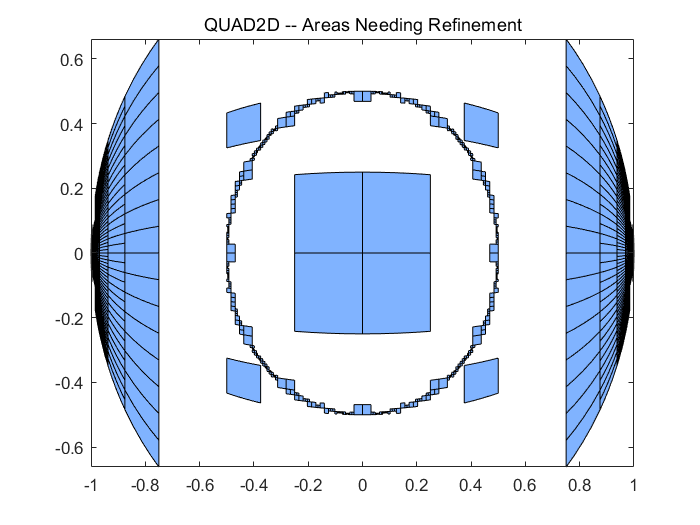

I =    0.981747938332597


fun=@(x,y)abs(x.^2+y.^2-0.25); %定义被积函数
c=@(x)-sqrt(1-x.^2); %内部积分下限函数
d=@(x)sqrt(1-x.^2); %内部积分上限函数
I=quad2d(fun,-1,1,c,d,'AbsTol',1e-8,...
'FailurePlot',true,'Singular',false) %一般区域二重积分求解

**8.5.5 triplequad()函数**

`MATLAB提供的triple quad(函数是用来求解长方体区域的三重积分`$\int_{x_m }^{x_M } \int_{y_m }^{y_M } \int_{z_m }^{z_M } f\left(x,y,z\right)\textrm{dxdydz}$，`的函数，该函数的调用格式为：`

`q=triplequad(fun，xmin，xmax，ymin，ymax，zmin，zmax，tol，@quadl，pl，p2，...)`

`其中，各参数的含义基本同函数dblquad() ，此处不再赘述。`

`【例8-28】求解三重积分问题`$I=\int_0^2 \int_0^{\pi } \int_0^{\pi } 4\textrm{xz}e^{-x^2 y-z^2 } \textrm{dzdydx}$

format long
f=@(x,y,z)4*x.*z.*exp(-x.^2.*y-z.^2);%定义被积函数
I=triplequad(f,0,2,0,pi,0,pi,1e-7,@quadl)%triple quad函数求解三重积分